# Proyecto Control y Sistema

## Valores para subsistema mecánido sonoro

r --> a partir de datasheet de IM69D130

rho = 1.2; %Densidad del aire [kg/m3]
v_sonido = 343.2;  %Velocidad del sonido en el aire [m/s]
d = 0.08;   %Distancia entre microfonos [m]
r = 0.0004; %Radio de membrana [m]
area_mem = pi*(r^2);    %Area de la membrana
vol = 0.001;  %Modificador de amplitud de la señal de audio
vel_caminata = 0.66; %Velocidad de caminata de la persona
r1 = 0.5; %Distancia del hablante al microfono 1 [m]
alfa_inicial = 180*(pi/180); %Angulo de posicionamiento de hablando con respecto al mic1

r_ambiente1 = 0.8;
r_ambiente2 = 0.7;
% r2 = sqrt((r1^2)+(d^2)-2*r1*d*cos(alfa));   %Distancia a mic2 utilizando teorema del coseno

## Valores para subsistema mecánico de la membrana

En la siguiente figura se muestra el subsistema eléctrico con una parte del eléctrico

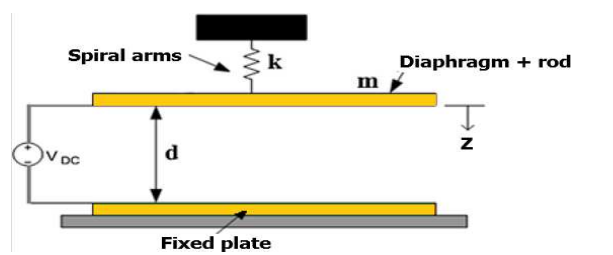Se agrego amortiguamiento

prof_mem --> grosor de membrana (Design Approaches of MEMS Microphones for Enhanced Performance [tabla de pag 4])

dens_mem --> densidad del grafeno (A Novel High Performance MEMS Capacitive Microphone [pag 2])

sens_mec --> Sensibilidad mecánica (A partir del gráfico de  Design Approaches of MEMS Microphones for Enhanced Performance [tabla de pag 10])

k --> Constante de rigidez (Despejado de ecuación 48 de A Novel High Performance MEMS Capacitive Microphone). Es un valor de rigidez que contempla la rigidez debido a la mecanica y a la electroestatica

cita --> 0.1, amortigua lo suficiente sin perder sensibilidad

prof_mem = 330e-6;   %Grosor de la membrana [m]
dens_mem = 2267;   %Densidad del material de la membrana [kg/m³]
sens_mec = 2e-9; %Sensibilidad mecanica del microfono [m/Pa]
cita = 0.005;
vol_mem = area_mem*prof_mem;    %Volumen de la membrana [m3]

m = vol_mem*dens_mem   %masa de membrana

m = 3.7604e-07

k = area_mem/(sens_mec)  %Rigidez del sistema

k = 251.3274

c = cita*2*sqrt(m*k)

c = 9.7216e-05

fr = (1/(2*pi))*sqrt(k/m)

fr = 4.1146e+03

## Valores para subsistema eléctrico

Se supone que hay aire entre membrana y placa fija

sg --> Sensing Gap (Design Approaches of MEMS Microphones for Enhanced Performance [tabla de pag 4])

La capacitancia se calcula como C = (perm*area_mem)/(sg - x) (Design Approaches of MEMS Microphones for Enhanced Performance [tabla de pag 5])

Q --> ChatGPT (Averiguar mejor en papers)

Vb = 0; %Voltage bias
perm = 8.854e-12; %Permitividad del aire [F/m]
sg = 2.2e-6; %Distancia entre membrana y placa fija [m]
Q = 1e-12; %Carga cel capacitor

## Parámetros para analisis de espectros

ventana_tiempo_analisis = 0.1;   %Segundos de ventana
n_nyquist_analisis = 2;
fs_analisis = 44100;

ventana_fft_analisis = ventana_tiempo_analisis*fs_analisis %Se coloca en Buffer

ventana_fft_analisis = 4410

zoh_freq_analisis = ventana_tiempo_analisis/ventana_fft_analisis;   %Se colocar en bloque ZOH

## Parámetros para FFT (acomodar)

ventana_tiempo = 0.1;   %Segundos de ventana
n_nyquist = 2;
fs = 44100;
f_co = 1800;

ventana_fft = ventana_tiempo*fs; %Se coloca en Buffer
delta_f = fs/ventana_fft;
pos_fco = f_co/delta_f;
zoh_freq = ventana_tiempo/ventana_fft   %Se colocar en bloque ZOH

zoh_freq = 2.2676e-05

## Valores para bloque de ganancias

cte_kp = 10; %Constante que está por las dudas que se necesite mas ganancia

## Valores para filtro FIR

ventana_FIR = 1;
fs = 44100; % Hz
fs_new = 4000; % Hz (submuestreo)

zoh_FIR = 1/fs;
cant_buffer_FIR = ventana_FIR*fs;
% y = zeros(1003,1);

t = 0:1/fs:ventana_FIR;

%% Filtrado
F_CO = f_co/fs; %Frecuencia de corte normalizada
N_max = round(1/(2*F_CO))+1; %N maximo


% y = [t(1:round(fs/fs_new):end)', zeros(length(t(1:round(fs/fs_new):end)), 1)]

## Suposiciones

- No hay retraso entre de captacion de sonido entre micrófonos, por lo que la técnica de procesamiento Beamfoming (formación de haces) no será necesaria. Solo se analizará la señal según la Amplitud y frecuencia de la señal.

- Espacio entre membrana y placa fija del micrófono tiene aire

- Q aprox a 1e-12 C

- El sonido se desplaza en aire

- Se utilizan micrófonos omnidireccionales (https://www.xataka.com/analisis/amazon-echo-input-analisis-caracteristicas-precio-especificaciones)

- El sonido ambiente tiene la misma frecuencia y amplitud en los dos microfonos, ya que es un sonido como si fuera un eco

## Consideraciones

- Como dato, se coloca la coordenada polar donde se encuentra el hablante respecto al microfono. Luego se calcula la distancia que tiene al otro microfono utilizando teorema del coseno

- La información de la posicion del hablante no será procesada, solo sirve para generar el dato de la presion resultante que le llegarán a los microfonos.

- La señal a analizar y controlar es la eléctrica, no las mecánicas.